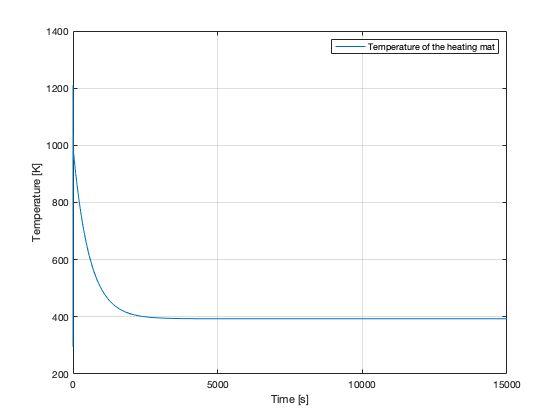

clear
clc
close all

% System matrices from physics-based model
A = [-7.017 7.017 0; 2.248 -2.248+3.32*10^(-5) 3.32*10^(-5); 0 2.496*10^(-4) -2.496*10^(-4)];
B = [24.938; 0; 0];
C = eye(3);
D = 0;

% Weighting factors
Q = diag([0.1 0.1 10]);
R = (0.01);

%Desired equilibrium states for the system
xd = [393.15; 393.15; 393.15];

%Initial conditions
x0 = [295.15; 295.15; 295.15];

%LQR solution
[K, S, E] = lqr(A, B, Q, R);

%Close loop system
sys = ss(A-B*K, -(A-B*K), C, D);

%Final simulation time 
tfinal = 15000;
time_total = 0:0.1:tfinal;

%Close loop input
closed_loop_input = [xd(1)*ones(size(time_total)); xd(2)*ones(size(time_total)); xd(3)*ones(size(time_total))];

%Simulation of the temperature response 
[output_closed_loop,time_closed_loop,state_closed_loop] = lsim(sys, closed_loop_input,time_total, x0);

%Plot of the temperature response 
figure(1);
plot(time_total,state_closed_loop(:,1))
xlabel('Time [s]')
ylabel('Temperature [K]')
legend('Temperature of the heating mat')
grid on;

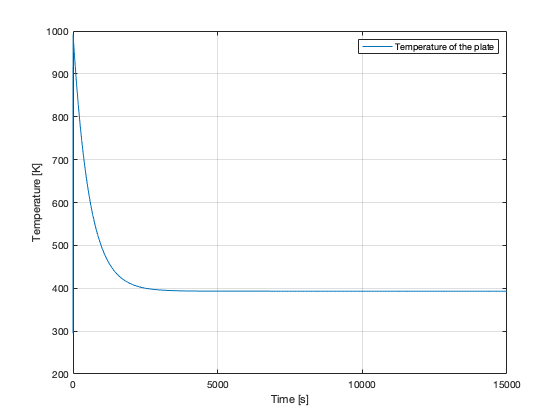


figure(2);
plot(time_total,state_closed_loop(:,2))
xlabel('Time [s]')
ylabel('Temperature [K]')
legend('Temperature of the plate')
grid on;

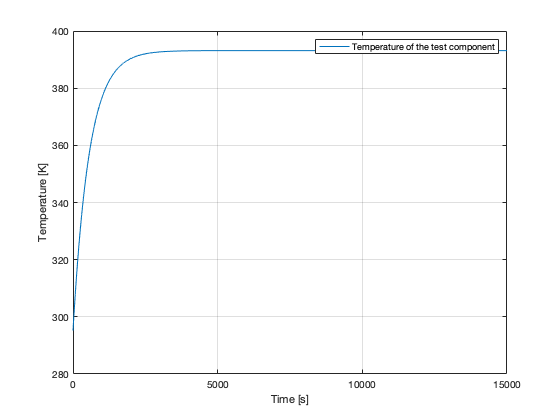


figure(3);
plot(time_total,state_closed_loop(:,3))
xlabel('Time [s]')
ylabel('Temperature [K]')
legend('Temperature of the test component')
grid on;